# Manivela

clear

%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Eje-manivela-Der.txt","Delimiter"," ");
%EjeManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Eje-manivela-Der.txt","Delimiter"," ");
EjeManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Eje-manivela-Der.txt","Delimiter"," ");


EjeManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

EjeManivela = 160×9 table
       T         Fz        Fy         Fx        F           Mz         My       Mx          M     
    _______    ______    _______    ______    ______    __________    _____    _____    __________

          0    22.236    -4396.9    1162.6      4548    8.6917e+05    21301    63933    8.7177e+05
    0.01532    23.424    -4631.8    1224.7      4791    9.1561e+05    22439    67349    9.1836e+05
    0.03064     24.61      -4866    1286.6    5033.3    9.6191e+05    23574    70754     9.648e+05
    0.04596    25.788    -5098.6      1348    5273.9    1.0079e+06    24700    74136     1.011e+06
    0.06128    26.956    -5328.9    1408.7      5512    1.0535e+06    258


%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\A3-Biela-manivela-Der.txt","Delimiter"," ");
%BielaManivela=readtable("MatLab cinetica\Reacciones manivela\B3-Biela-manivela-Der.txt","Delimiter"," ");
BielaManivela=readtable("MatLab cinetica\Reacciones manivela\C3-Biela-manivela-Der.txt","Delimiter"," ");


BielaManivela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"]

BielaManivela = 160×9 table
       T          Fz         Fy        Fx         F          Mz          My         Mx          M   
    _______    ________    ______    _______    ______    ________    ________    _______    _______

          0    -0.32609    4547.9    0.00736    4547.9    -0.00813    -0.00049    -0.0176    0.01939
    0.01532    -0.32732    4790.9    0.00739    4790.9           0           0          0          0
    0.03064    -0.32855    5033.1    0.00743    5033.1           0           0          0          0
    0.04596    -0.32977    5273.7    0.00747    5273.7           0           0          0          0
    0.06128    -0.33097    5511.9    0.00752    5511.9     



D_manivela=0.08

D_manivela = 0.0800

d_eje=0.06

d_eje = 0.0600

b_manivela=0.0508

b_manivela = 0.0508

h_manivela=D_manivela

h_manivela = 0.0800

W=0.018;
H=0.011;
L=b_manivela;

%1045 HR
Sut=630  

Sut = 630

Sy=530

Sy = 530

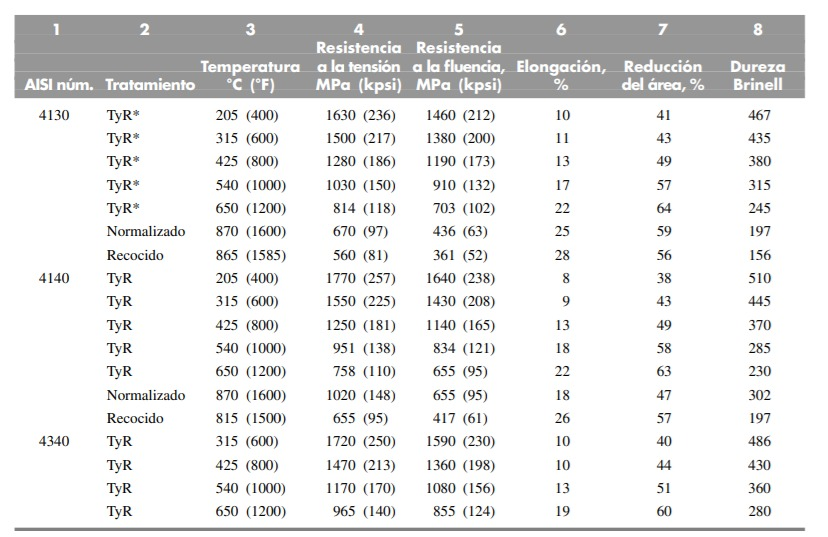

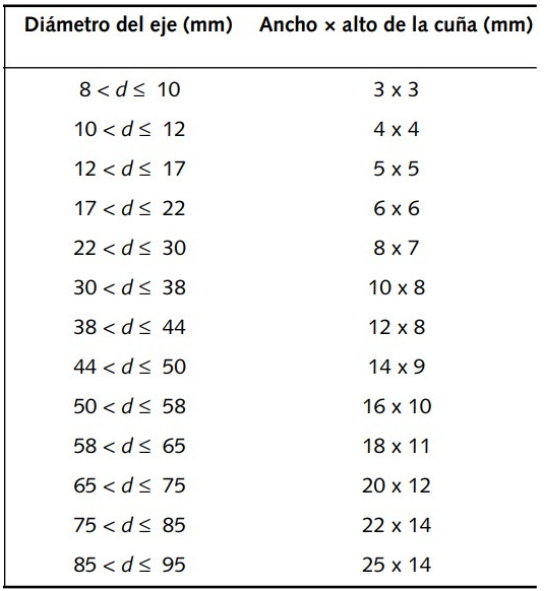


vectorTiempo=BielaManivela.T;
ExtremoEjeFy=-EjeManivela.Fy;
ExtremoEjeFz=-EjeManivela.Fz;
ExtremoEjeFx=EjeManivela.Fx;
EjeTorqueMz=-EjeManivela.Mz/1000;
EjeTorqueMy=-EjeManivela.My/1000;
EjeTorqueMx=EjeManivela.Mx/1000;



ExtremoBielaFy=BielaManivela.Fz;
ExtremoBielaFz=BielaManivela.Fx;
ExtremoBielaFx=BielaManivela.Fy;



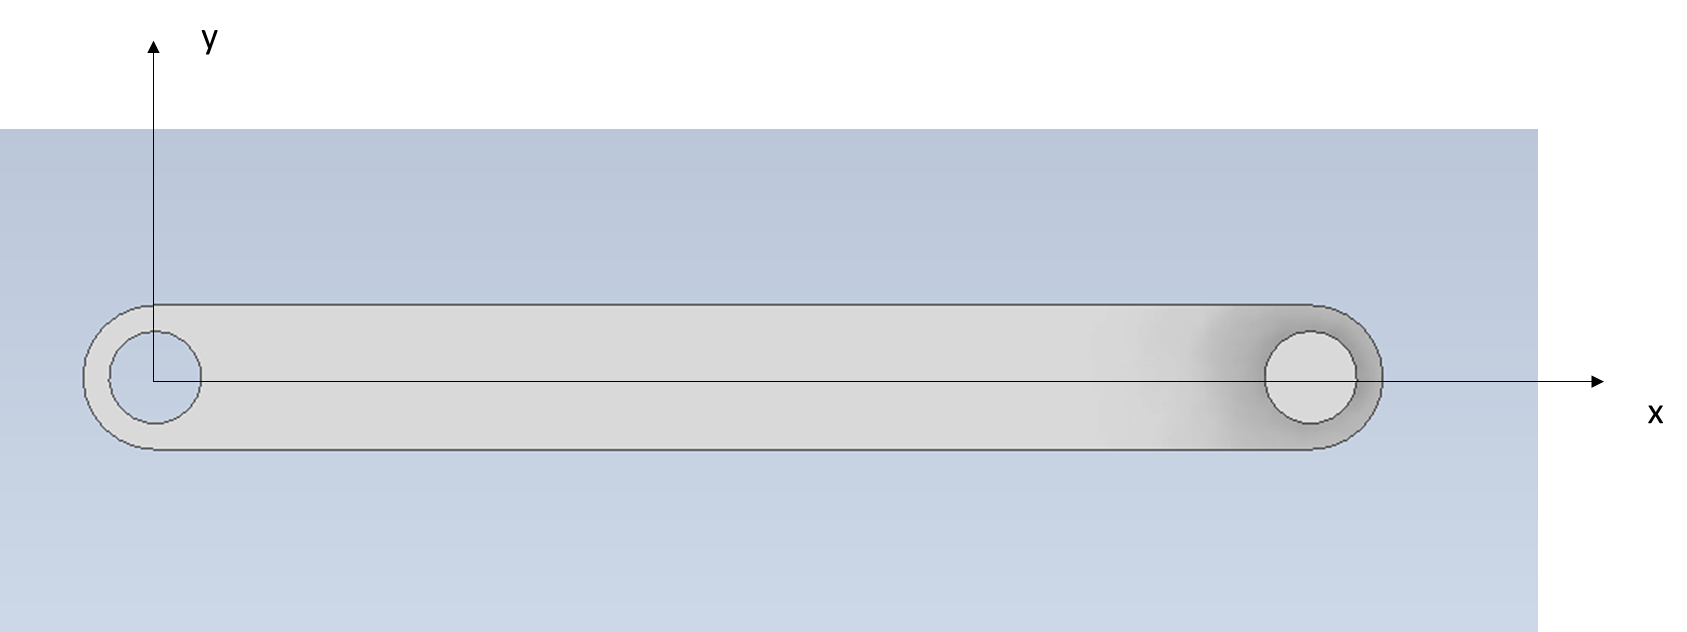

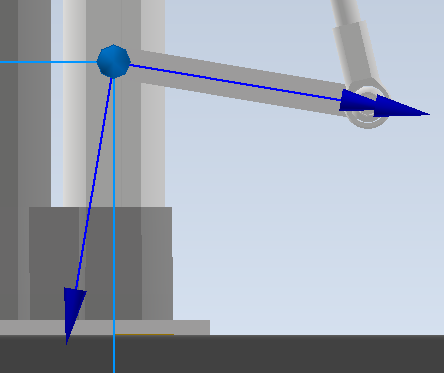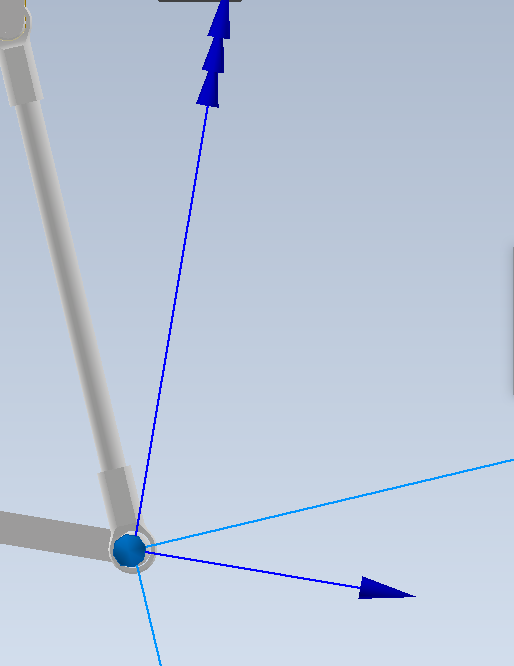

difFx=ExtremoBielaFx+ExtremoEjeFx;
difFy=ExtremoBielaFy+ExtremoEjeFy;
difFz=ExtremoEjeFz+ExtremoBielaFz;


## Análisis unión biela-manivela

ExtremoBielaFy

ExtremoBielaFz

ExtremoBielaFx

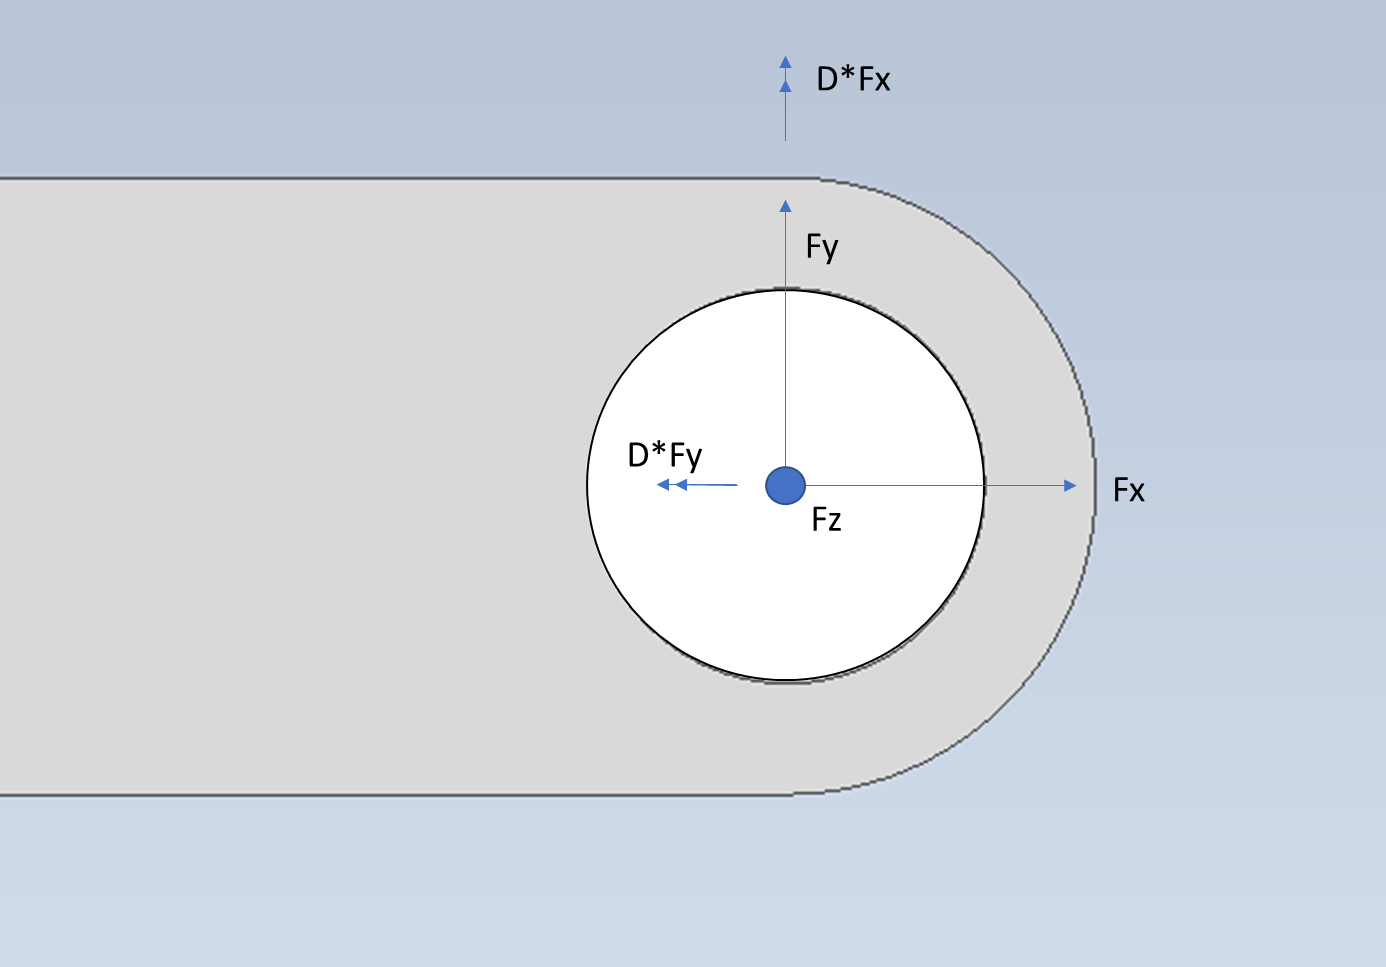

h_bm=0.017;
D_bm=0.0254;

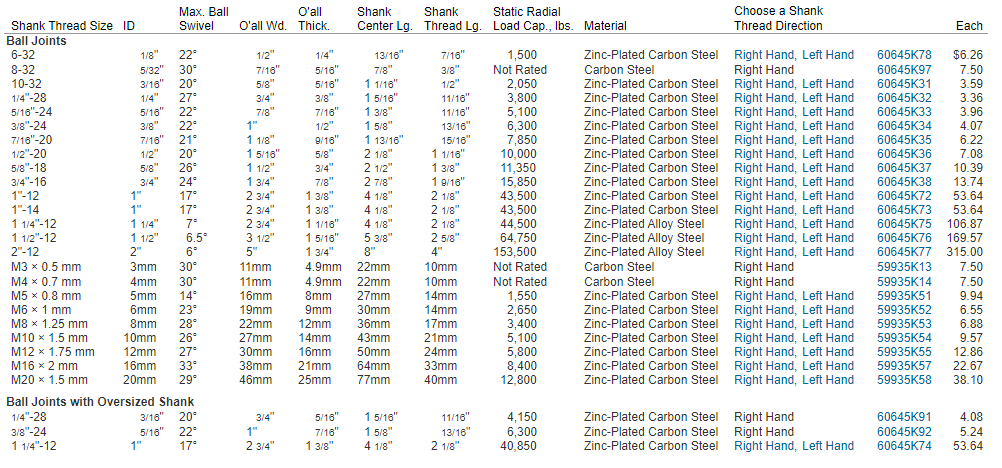

https://www.mcmaster.com/ball-joints/internally-threaded-ball-joint-rod-ends/

I=pi*D_bm^4/64;
A=pi*D_bm^2/4;
My=h_bm*ExtremoBielaFx;
Mx=h_bm*ExtremoBielaFy;
MT=sqrt(My.^2+Mx.^2);

Sigma_t=MT*0.5*D_bm/I;
Sigma_c=-MT*0.5*D_bm/I;
Sigma_normal=ExtremoBielaFz/A;
ExtremoBielaFz

ExtremoBielaFz =     0.0074
    0.0074
    0.0074
    0.0075
    0.0075
    0.0076
    0.0076
    0.0077
    0.0078
    0.0079


Sigma_t_Total=(Sigma_normal+Sigma_t)

Sigma_t_Total = 	1.0e+07 *

    4.8057
    5.0625
    5.3184
    5.5727
    5.8243
    6.0726
    6.3155
    6.5556
    6.7779
    6.7382


Sigma_c_Total=(Sigma_normal+Sigma_c)

Sigma_c_Total = 	1.0e+07 *

   -4.8057
   -5.0625
   -5.3184
   -5.5727
   -5.8243
   -6.0726
   -6.3155
   -6.5556
   -6.7779
   -6.7382


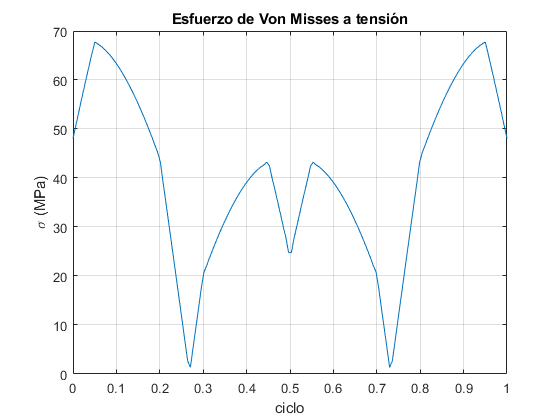





plot(linspace(0,1,160),Sigma_t_Total/1000000)
grid on
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses a tensión")

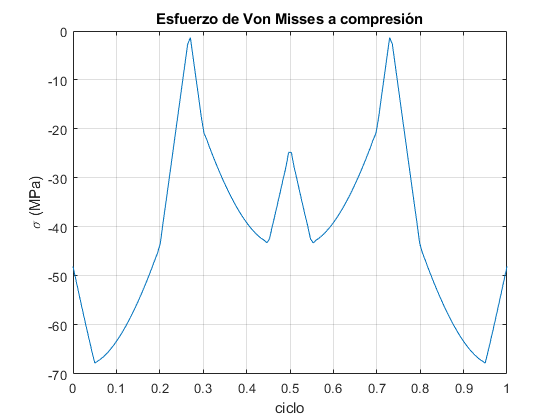

plot(linspace(0,1,160),Sigma_c_Total/1000000)
grid on
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses a compresión")

### Fatiga

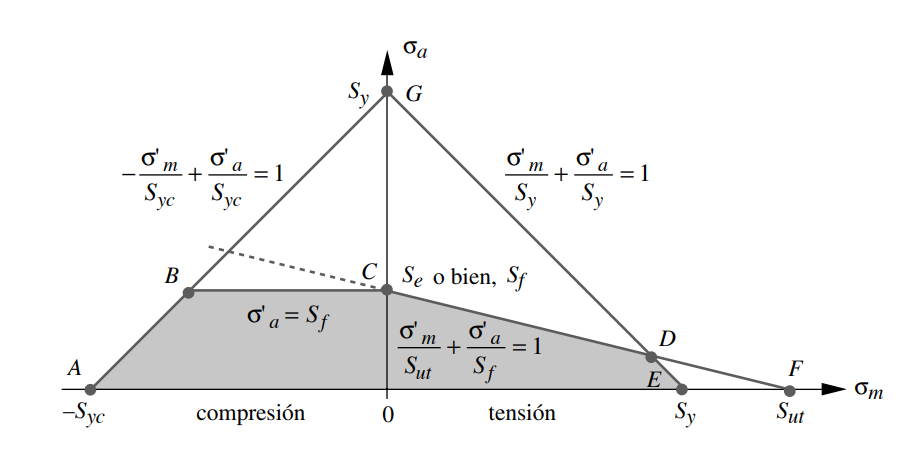

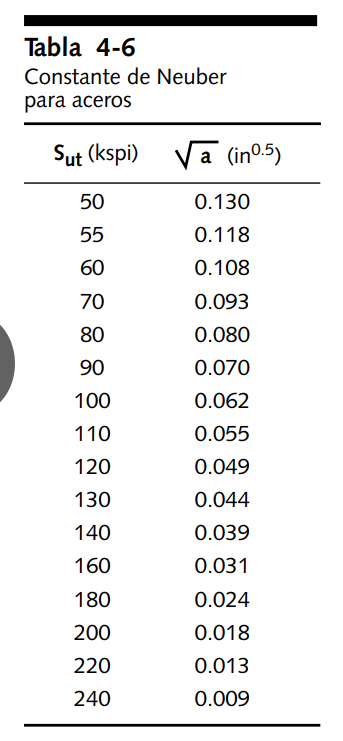

kt=2;
neuberF=0.07; %Corregir neuber
neuberT=0.055;
radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1);
KfsmSold=1+qTorsion*(kt-1);



mega=1000000;

sigmaAc=KfSold*0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega;   %esfuerzo alternante
sigmaMc=KfSold*0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega;   %esfuerzo medio

sigmaAt=KfSold*0.5.*abs(max(Sigma_t_Total)-min(Sigma_t_Total))/mega;   %esfuerzo alternante
sigmaMt=KfSold*0.5.*abs(max(Sigma_t_Total)+min(Sigma_t_Total))/mega;

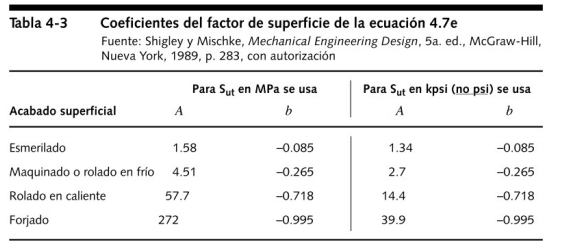

#### Factores de corrección

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;

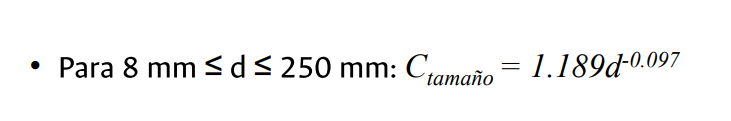

Ctam=1.189*(D_bm*1000)^(-0.097);
Ccon=0.814; % 99%
if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end

Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman modificado

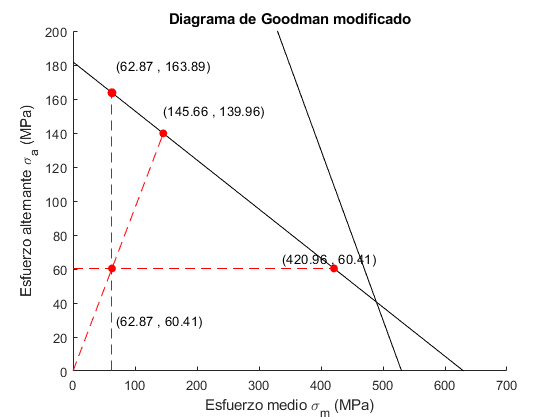

FS1 = 2.7130

FS2 = 2.3170

FS3 = 6.6961

FS_union_biela_t = 2.3170

FS_union_biela_t=diagramaGoodman(sigmaAt,sigmaMt,Sut,Sy,Se,true)

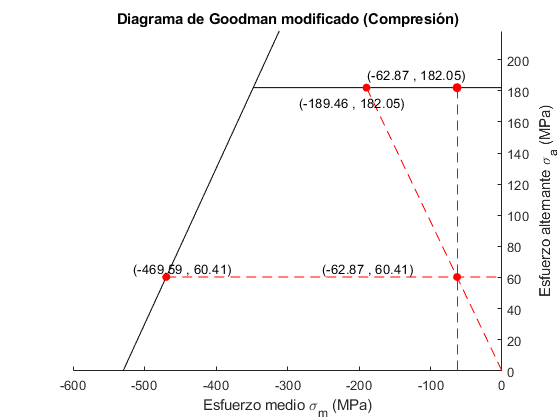

FS1 = 3.0137

FS2 = 3.0137

FS3 = 7.4697

FS_union_biela_c = 3.0137


FS_union_biela_c=diagramaGoodman(sigmaAc,sigmaMc,Sut,Sy,Se,false)

## Análisis unión eje-manivela

### Análisis por cuña

A_seccion=0.5*b_manivela*(D_manivela-d_eje)

A_seccion = 5.0800e-04

r_externo=0.5*D_manivela;
b=b_manivela

b = 0.0508

H=D_manivela

H = 0.0800

h=d_eje

h = 0.0600

J=b/12*(H*(H^2+b^2)-h*(h^2+b^2))

J = 1.4716e-06

Iz=b/12*(H^3-h^3)

Iz = 1.2531e-06

Iy=b^3/12*(H-h)

Iy = 2.1849e-07


Kt=2;
Kts=2.75;

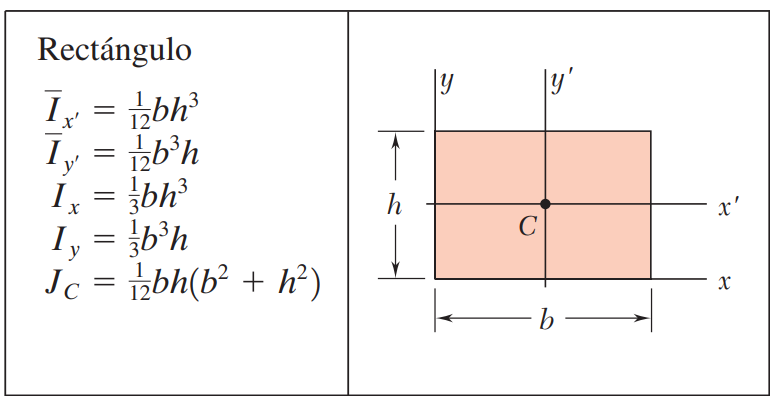

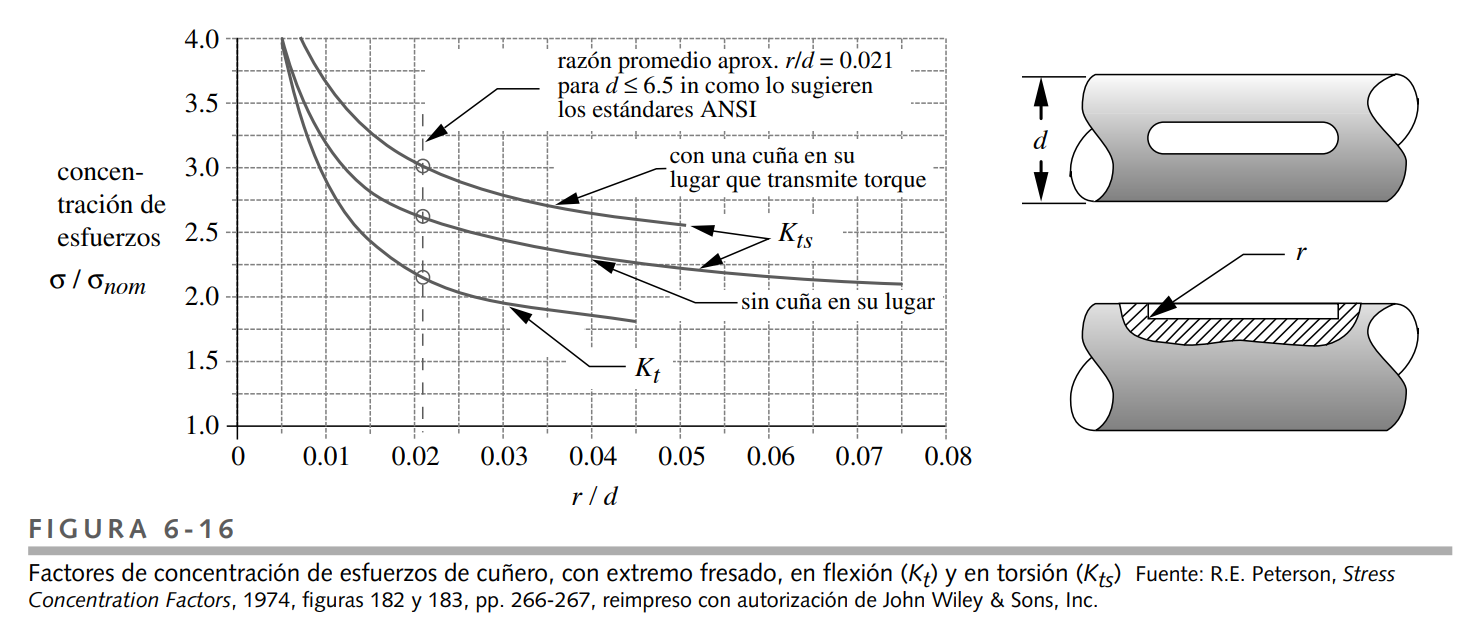

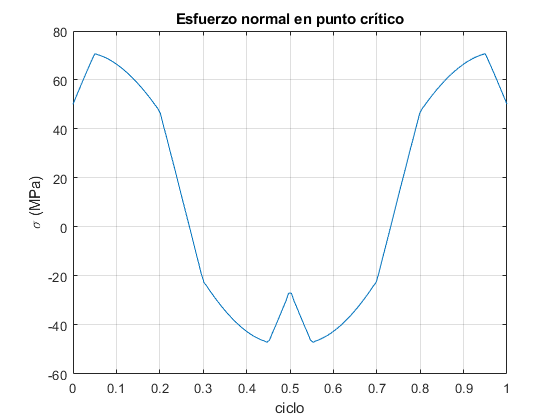

radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1);
Kfsm=1+qTorsion*(Kts-1);

r=sqrt(r_externo^2+(0.5*b)^2);


ang=atan(D_manivela/b)*180/pi;



Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/Iz; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*0.5*b/Iy; %Momento flector: +z->i,-z->-i

tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r/J; %Momento cortante:  +y->+k,-y->-k

Sigma_total=Kf*(Sigma_Fx+Sigma_Mz+sigma_My);
tau_total=Kfsm*sqrt((tau_Vy-tau_Mx*cos(ang)).^2+(tau_Vz-tau_Mx*sin(ang)).^2);

plot(linspace(0,1,160),Sigma_total/1000000)
title("Esfuerzo normal en punto crítico")
xlabel("ciclo")
ylabel("\sigma (MPa)")
grid on

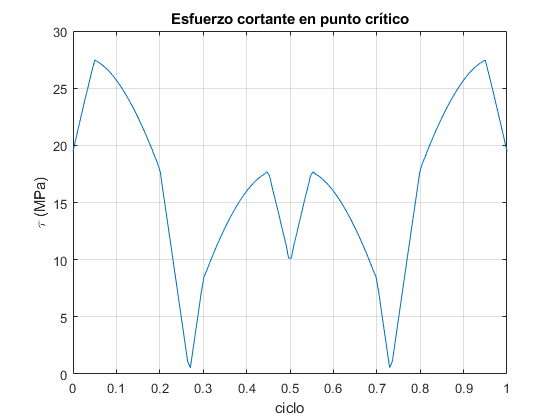

plot(linspace(0,1,160),tau_total/1000000)
xlabel("ciclo")
ylabel("\tau (MPa)")
title("Esfuerzo cortante en punto crítico")
grid on



Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total))

Sigma_Alternante = 5.8922e+07

Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total))

Sigma_Medio = 1.1835e+07

Tau_Alternante=0.5*(max(tau_total)-min(tau_total))

Tau_Alternante = 1.3461e+07

Tau_Medio=0.5*(max(tau_total)+min(tau_total))

Tau_Medio = 1.4011e+07


sigmaA=sqrt((Sigma_Alternante).^2+3*(Tau_Alternante).^2)/mega

sigmaA = 63.3668

sigmaM=sqrt((Sigma_Medio).^2+3*(Tau_Medio).^2)/mega

sigmaM = 27.0004

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5

A_95 = 1.2700e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0129


Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9280


Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 149.9978

#### Diagrama de Goodman

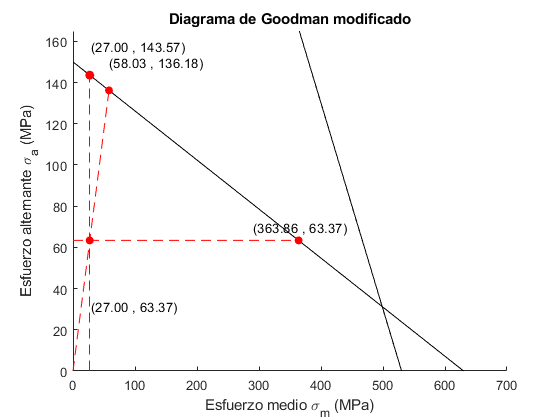

FS1 = 2.2657

FS2 = 2.1491

FS3 = 13.4759

FS_cortante_eje_cuna = 2.1491

FS_eje_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero Cortante




Sut=630  

Sut = 630

Sy=530

Sy = 530


%parametros cuña


A_t=W*L

A_t = 9.1440e-04

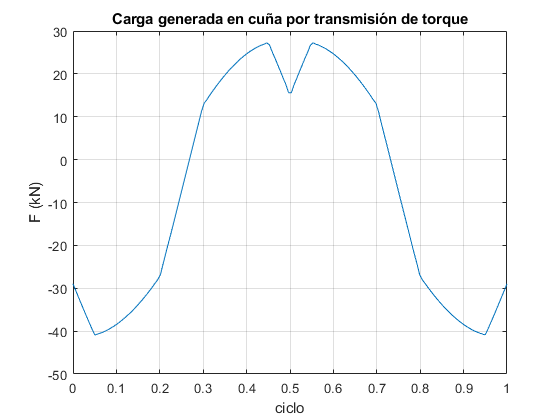


r_eje=0.5*d_eje;
Torque=EjeTorqueMz;
r_cuna=0.03*d_eje;


Carga_cortante=Torque/r_eje;



plot(linspace(0,1,160),Carga_cortante/1000)
xlabel("ciclo")
ylabel("F (kN)")
title("Carga generada en cuña por transmisión de torque")
grid on

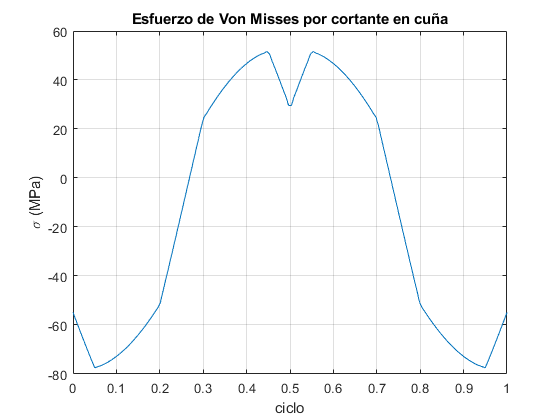



tau_V=Carga_cortante/A_t;

plot(linspace(0,1,160),sqrt(3)*tau_V/1000000)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses por cortante en cuña")
grid on




sigmaA=abs(sqrt(3)*0.5*(max(tau_V)-min(tau_V))/mega)

sigmaA = 64.5592

sigmaM=abs(sqrt(3)*0.5*(max(tau_V)+min(tau_V))/mega)

sigmaM = 12.9190

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05*L*W

A_95 = 4.5720e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0244

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.8721


if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 201.3752

#### Diagrama de Goodman

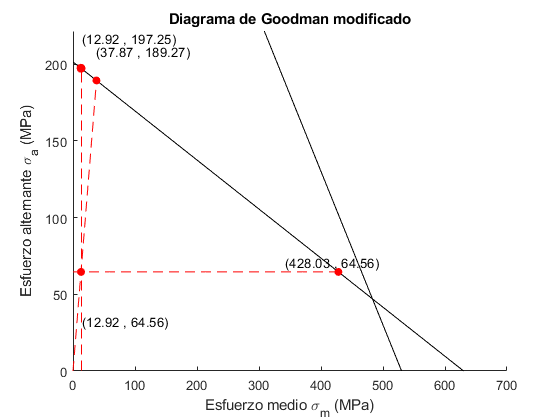

FS1 = 3.0553

FS2 = 2.9317

FS3 = 33.1317

FS_cortante_cuna = 2.9317

FS_cortante_cuna=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

## Análisis cuña-cuñero aplastamiento

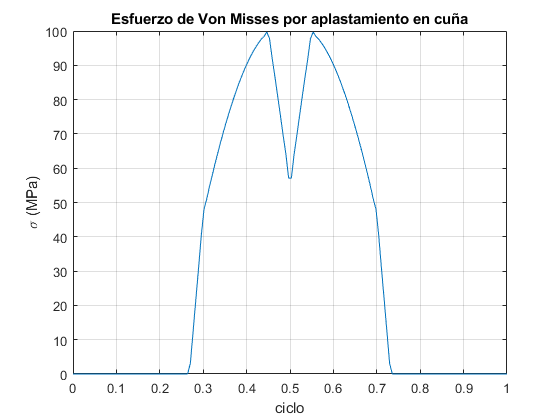


Sec_ap=5.382*0.001;
A_sigma=Sec_ap*L;
sigma_V=Carga_cortante/A_sigma;
sigma_V1=sigma_V;
sigma_V1(sigma_V1<0)=0;
sigma_V2=sigma_V;
sigma_V2(sigma_V2>0)=0;
sigma_V2=abs(sigma_V2);



plot(linspace(0,1,160),sigma_V1/1000000)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses por aplastamiento en cuña")
grid on

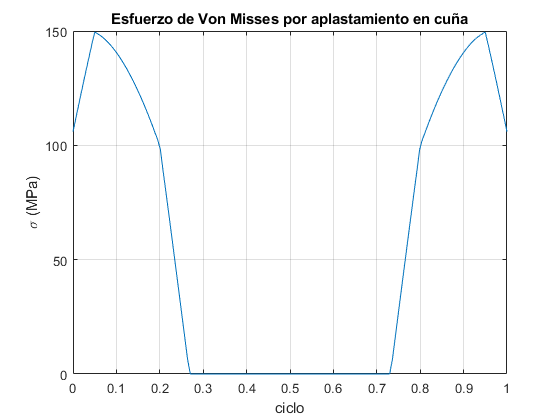



plot(linspace(0,1,160),sigma_V2/1000000)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses por aplastamiento en cuña")
grid on



%sigmaA=0.5*(max(sigma_V)-min(sigma_V))/mega
%sigmaM=0.5*(max(sigma_V)+min(sigma_V))/mega

sigmaA1=0.5*max(sigma_V1)/mega

sigmaA1 = 49.8571

sigmaM1=0.5*max(sigma_V1)/mega

sigmaM1 = 49.8571


sigmaA2=0.5*max(sigma_V2)/mega

sigmaA2 = 74.8028

sigmaM2=0.5*max(sigma_V2)/mega

sigmaM2 = 74.8028

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;

A_95=0.05* A_sigma

A_95 = 1.3670e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0134

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9247


SeSC=0.5*Sut;
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 213.5188

#### Diagrama de Goodman

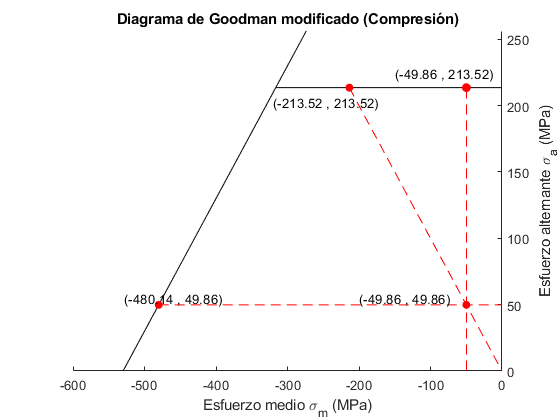

FS1 = 4.2826

FS2 = 4.2826

FS3 = 9.6304

FS_aplastamiento_cuna_1 = 4.2826

%FS_aplastamiento_cuna_1=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,false)

FS_aplastamiento_cuna_1=diagramaGoodman(sigmaA1,sigmaM1,Sut,Sy,Se,false)

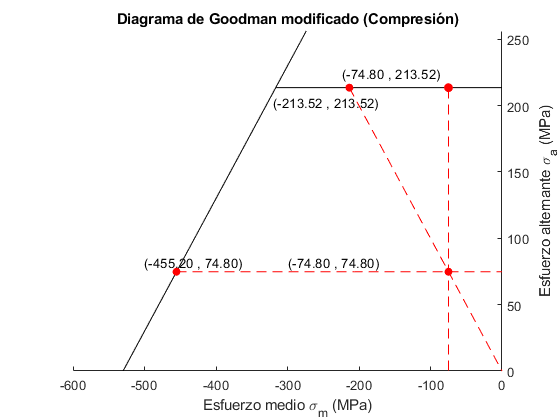

FS1 = 2.8544

FS2 = 2.8544

FS3 = 6.0853

FS_aplastamiento_cuna_2 = 2.8544


FS_aplastamiento_cuna_2=diagramaGoodman(sigmaA2,sigmaM2,Sut,Sy,Se,false)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end




figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(4*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(3*sigmaM,1.05*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,0.95*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end